# Owen Rogg Personal Project #1

%{
Made by Owen Rogg, April 20th 2026
Personal Project 1
Display a graph of a line to the n'th degree where the user
can input the degree line they would like to see. Can also ask
for the left and right boundary.

%}

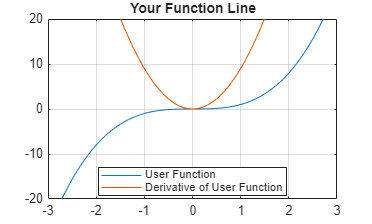

%Clear everything for a fresh start
clear
clc
close all
xleftask=inputdlg('Left Boundary?');
xleft=str2num(xleftask{1});
xrightask=inputdlg('Right Boundary?');
xright=str2num(xrightask{1});
x=(xleft):.1:(xright);
nask=inputdlg('What degree function?');
n= str2num(nask{1});
y=x.^n;
yupask=inputdlg('Max Y?');
yup =str2num(yupask{1});
ydwnask = inputdlg('Min Y?');
ydwn = str2num(ydwnask{1});

figure
plot(x,y);

title('Your Function Line')
grid ("on");
hold on
d=((n*x).^((n)-1));
plot(x,d)
ylim([ydwn yup]);
xlim=[xleft xright];


legend('User Function','Slope of User Function',Location='best')